## Concept Check: Introduction to Bag of Features

Q1. To extract feature descriptors from images and prepare them as inputs to train a classification model.

Q2. It allows you to use automatic feature extraction algorithms more easily. / It can find useful features that may not be obvious from examining the images.

Q3. More

Q4. 0

## Classifying Images With Bag of Features

imdsFolder = "../../Data/MathWorks Images/Roadside Ground Cover";
imds = imageDatastore(imdsFolder,"IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain,imdsTest] = splitEachLabel(imds,0.85,"randomized");
bag = bagOfFeatures(imdsTrain,"GridStep",[24 24],"BlockWidth",[96 128]);

Bag-Of-Features を作成しています。
-------------------------
* イメージ カテゴリ 1: No Snow
* イメージ カテゴリ 2: Snow
* Grid メソッドを使用して特徴点の位置を選択します。
* 選択した特徴点の位置から SURF 特徴を抽出します。
** GridStep は [24 24]、BlockWidth は [96 128] です。

* 170 個のイメージから特徴を抽出しています...完了。183600 個の特徴を抽出しました。

* 各カテゴリから最も強い特徴の 80 % を保持します。

* 500 ワードのビジュアル ボキャブラリを作成します。
* レベルの数: 1
* 分岐因子: 500
* クラスタリング ステップの数: 1

* [ステップ 1/1] ボキャブラリ レベル 1 をクラスタリングします。
* 特徴の数 : 146880
* クラスターの数 : 500
* クラスターの中心を初期化しています...100.00%.
* クラスタリングしています...100 回中 19 回の反復 (~0.20 seconds/iteration) を完了...19 回の反復で収束しました。

* Bag-Of-Features の作成が完了しました。



predFeatsTrain = encode(bag,imdsTrain);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: No Snow
* イメージ カテゴリ 2: Snow
* 170 個のイメージをエンコードしています...完了。



featNames = "f" + string(1:500);
gcTableBag = array2table(predFeatsTrain,"VariableNames",featNames);
gcTableBag.labels = categorical(imdsTrain.Labels);
predFeatsTest = encode(bag,imdsTest);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: No Snow
* イメージ カテゴリ 2: Snow
* 30 個のイメージをエンコードしています...完了。


predTableTest = array2table(predFeatsTest,"VariableNames",featNames);
predTableTest.labels = categorical(imdsTest.Labels);

classificationLearner

## Practice Using Bag of Features

% filePath = uigetdir;
filePath = 'C:\Users\kenconnor\Desktop\playground_matlab\Computer Vision for Engineering and Science\Data\Concrete';
dsConcrete = imageDatastore(filePath,"IncludeSubfolders",true,"LabelSource","foldernames");
[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomized");
if 0
    nFiles = length(dsTrain.Files);
    randIdxs = randperm(nFiles);
    randIdxs = randIdxs(1:100);
    dsTrain = subset(dsTrain,randIdxs);
end

tic
bag = bagOfFeatures(dsTrain);

Bag-Of-Features を作成しています。
-------------------------
* イメージ カテゴリ 1: Negative
* イメージ カテゴリ 2: Positive
* Grid メソッドを使用して特徴点の位置を選択します。
* 選択した特徴点の位置から SURF 特徴を抽出します。
** GridStep は [8 8]、BlockWidth は [32 64 96 128] です。

* 800 個のイメージから特徴を抽出しています...完了。2508800 個の特徴を抽出しました。

* 各カテゴリから最も強い特徴の 80 % を保持します。

* 500 ワードのビジュアル ボキャブラリを作成します。
* レベルの数: 1
* 分岐因子: 500
* クラスタリング ステップの数: 1

* [ステップ 1/1] ボキャブラリ レベル 1 をクラスタリングします。
* 特徴の数 : 2007040
* クラスターの数 : 500
* クラスターの中心を初期化しています...100.00%.
* クラスタリングしています...100 回中 40 回の反復 (~2.82 seconds/iteration) を完了...40 回の反復で収束しました。

* Bag-Of-Features の作成が完了しました。



T = toc

T = 183.7031


predFeats = encode(bag,dsTrain);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: Negative
* イメージ カテゴリ 2: Positive
* 800 個のイメージをエンコードしています...完了。


featNames = "f" + string(1:500);
gcTableBag = array2table(predFeats,"VariableNames",featNames);
gcTableBag.labels = categorical(dsTrain.Labels);

classificationLearner

tic
bagGridLarge = bagOfFeatures(dsTrain,"GridStep",[32 32]);

Bag-Of-Features を作成しています。
-------------------------
* イメージ カテゴリ 1: Negative
* イメージ カテゴリ 2: Positive
* Grid メソッドを使用して特徴点の位置を選択します。
* 選択した特徴点の位置から SURF 特徴を抽出します。
** GridStep は [32 32]、BlockWidth は [32 64 96 128] です。

* 800 個のイメージから特徴を抽出しています...完了。156800 個の特徴を抽出しました。

* 各カテゴリから最も強い特徴の 80 % を保持します。

* 500 ワードのビジュアル ボキャブラリを作成します。
* レベルの数: 1
* 分岐因子: 500
* クラスタリング ステップの数: 1

* [ステップ 1/1] ボキャブラリ レベル 1 をクラスタリングします。
* 特徴の数 : 125440
* クラスターの数 : 500
* クラスターの中心を初期化しています...100.00%.
* クラスタリングしています...100 回中 18 回の反復 (~0.22 seconds/iteration) を完了...18 回の反復で収束しました。

* Bag-Of-Features の作成が完了しました。



TGL = toc

TGL = 8.7909


predFeatsGridLarge = encode(bagGridLarge,dsTrain);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: Negative
* イメージ カテゴリ 2: Positive
* 800 個のイメージをエンコードしています...完了。


featNames = "f" + string(1:size(predFeatsGridLarge,2));
predTableGridLarge = array2table(predFeatsGridLarge,"VariableNames",featNames);
predTableGridLarge.labels = categorical(dsTrain.Labels);

validationAccuracy = 99.1;
validationAccuracyGL = 98.1;
array2table([[validationAccuracy; validationAccuracyGL], ...
    [T; TGL]],...
    VariableNames=["Accuracy","Run Time (s)"],...
    RowNames=["Default","Grid Small"])

ans = 2×2 table
                  Accuracy    Run Time (s)
                  ________    ____________

    Default         99.1          80.87   
    Grid Small      98.1         8.7909   


## Practice Quiz: Practice Using Bag of Features

Q1. `bag` = bagOfFeatures(dsTrain); % Default parameters

Q2. bag = bagOfFeatures(dsTrain) % Default parameters

## Project: Introduction to Ground Cover Classification

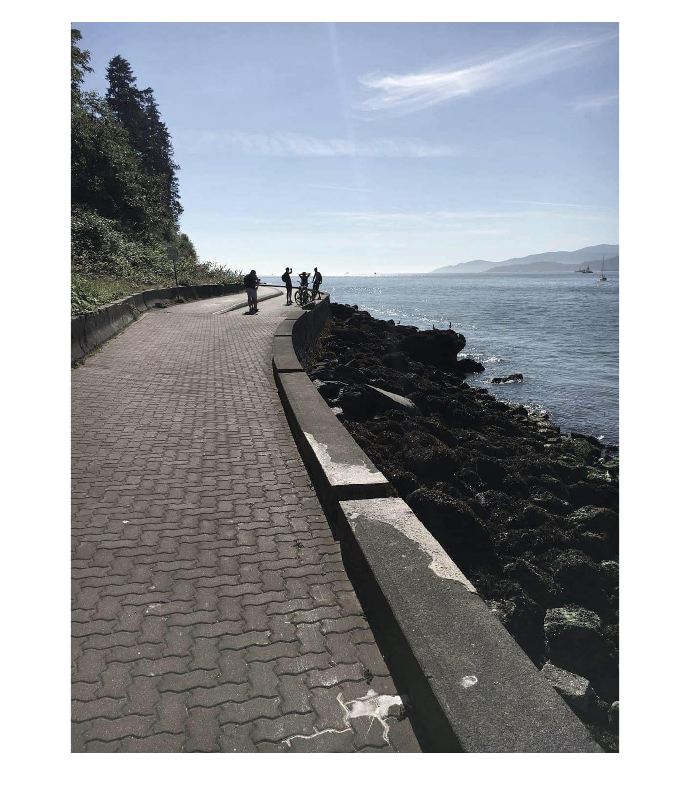

img = imread("ocean.jpg");
imshow(img)

load("gcClassifierSaturation.mat")
gcClassifierSaturation

gcClassifierSaturation = フィールドをもつ struct :
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'avgSat'  'stdSat'}
    ClassificationSVM: [1×1 ClassificationSVM]
                About: 'This struct is a trained model exported from Classification Learner R2022a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


load("gcClassifierBag.mat","gcClassifierBag");
gcClassifierBag

gcClassifierBag = フィールドをもつ struct :
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {1×500 cell}
    ClassificationSVM: [1×1 ClassificationSVM]
                About: 'This struct is a trained model exported from Classification Learner R2022a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


load("bag.mat","bag")
bag

bag =   bagOfFeatures のプロパティ:

       NumVisualWords: 500
       TreeProperties: [1 500]
    StrongestFeatures: 0.8000
       PointSelection: 'Grid'
             GridStep: [24 24]
           BlockWidth: [96 128]
              Upright: 1


imgHSV = rgb2hsv(img);
avgSat = mean(imgHSV(:,:,2),"all");
stdSat = std2(imgHSV(:,:,2));
gcTableSaturation = table(avgSat,stdSat);
gcTableSaturation.prediction = gcClassifierSaturation.predictFcn(gcTableSaturation)

gcTableSaturation = 1×3 table
    avgSat    stdSat     prediction
    ______    _______    __________

    0.1436    0.07314       Snow   


predFeat = encode(bag,img);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージのエンコード中...完了。


featNames = "f" + string(1:size(predFeat,2));
gcTableBag = array2table(predFeat,"VariableNames",featNames)

gcTableBag = 1×500 table
      f1          f2           f3          f4          f5          f6          f7          f8          f9           f10          f11         f12          f13       f14    f15     f16       f17         f18         f19        f20          f21         f22          f23          f24         f25         f26         f27         f28         f29       f30    f31      f32         f33         f34          f35         f36         f37        f38         f39         f40          f41          f42         f43        f44         f45         f46         f47         f48         f49         f50         f51       f52       f53         f54         f55         f56         f57        f58          f59         f60        f61         f62          f63       f64       f65       f66      f67       f68      f69         f70         f71         f72         f73         f74          f75         f76         f77         f78         f79         f80         f81         f82         f83        f84    

gcTableBag.prediction = gcClassifierBag.predictFcn(gcTableBag)

gcTableBag = 1×501 table
      f1          f2           f3          f4          f5          f6          f7          f8          f9           f10          f11         f12          f13       f14    f15     f16       f17         f18         f19        f20          f21         f22          f23          f24         f25         f26         f27         f28         f29       f30    f31      f32         f33         f34          f35         f36         f37        f38         f39         f40          f41          f42         f43        f44         f45         f46         f47         f48         f49         f50         f51       f52       f53         f54         f55         f56         f57        f58          f59         f60        f61         f62          f63       f64       f65       f66      f67       f68      f69         f70         f71         f72         f73         f74          f75         f76         f77         f78         f79         f80         f81         f82         f83        f84    

## Graded Quiz: Bag of Features

Q1. Creating a visual vocabulary

Q2. 6

Q3. 4

Q4. 同じ位置に大きい四角形。粗い方。

Q5. Grid (Detectionだと背景の特徴が多く出過ぎる)

Q6. decrease

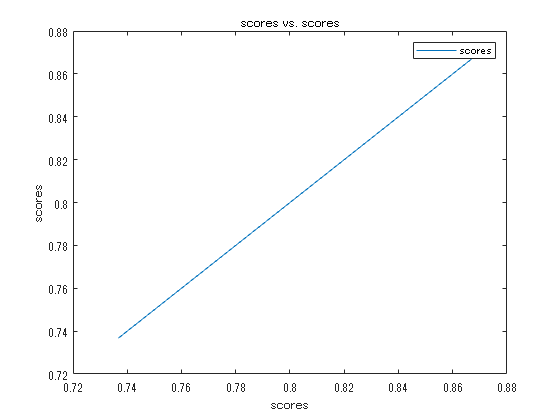

% 作成 scores と scores の plot
h = plot(scores,scores,"DisplayName","scores");

% xlabel, ylabel, title および legend の追加
xlabel("scores")
ylabel("scores")
title("scores vs. scores")
legend

y = 1.4;
% myfolder = uigetdir
myfolder = 'C:\Users\kenconnor\Desktop\playground_matlab\Image Processing for Engineering and Science\Data\Data\Concrete Crack Images';
imds = imageDatastore(myfolder,"IncludeSubfolders",true,"LabelSource","foldernames");